%path='Z:\Third report\Third report\Week 12-13\Exercise1\figures\';
path='P:\EPFL\Troisième année\Semestre 2\Computationnal physics III\Third report\Rendu\Part 2 Exercise 1\figures\'

path = 'P:\EPFL\Troisième année\Semestre 2\Computationnal physics III\Third report\Rendu\Part 2 Exercise 1\figures\'

clear all
close all
A=[1 1 ; 1 2 ; 1 3];
b=[1 ; 1.2 ; 1.1];
A_=pinv(A);
n=10;
least_square_sol=A_*b;

r=@(x,y) norm(A*[x';y']-b);
%--------------------
% points=cell(n);
% pas=0.01;
% for i=1:n
%     for j=1:n
%         points{i,j}=[least_square_sol(1)+(i-n/2)*pas ;least_square_sol(2)+(j-n/2)*pas];
%     end
% end
% r_ = cellfun(r,points)
xdelta=3.5;
ydelta=1;

figure
fcontour(r,[least_square_sol(1)-xdelta, least_square_sol(1)+xdelta, least_square_sol(2)-ydelta, least_square_sol(2)+ydelta],'LevelStep',0.3,'MeshDensity',200)

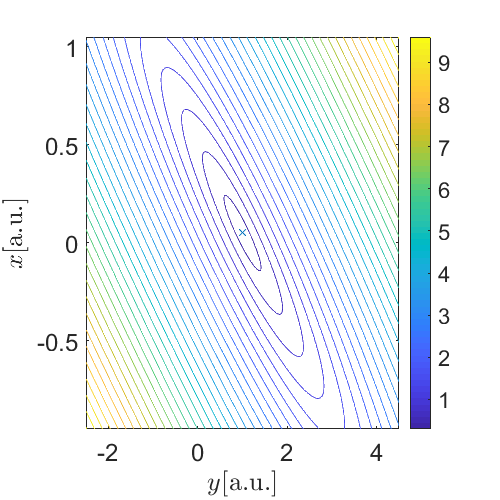

colorbar
hold on
plot(least_square_sol(1),least_square_sol(2),'x')
ylabel('$x\mathrm{[a.u.]}$','Interpreter','latex','FontSize',18);
xlabel('$y\mathrm{[a.u.]}$','Interpreter','latex','FontSize',18);
set(gca,'FontSize',18)

%saveas(gcf,strcat('Z:\Third report\Third report\Week 12-13\Exercise1\figures\','contourlevel'),'png');

% contour(r,x)